# **Lab 1:  Random variables and estimation theory**

**Statistical Signal Processing (5CTA0) - Lab Assignment**

Lecturers: Simona Turco (Flux 7.076)

Assistants: Yizhou Huang (Flux 7.078), Agata Barbagini (Flux 7.079), Xueting Li (Flux 7.079), Luan Fiorio (Flux 7.066)

**Students (Name + IDs):**

**Group #: **

## General info and guidelines

To complete and submit the Labs:

`•`All students must register on Canvas.

`•`Each lab will be carried out in groups of 3 students, randomly assigned on Canvas.

`•`All information and data will be available on Canvas.

`•`Each group must carry out all assignments of the Lab and hand in a report for each Lab.

`•`**The report is obtained by exporting this matlab live script as pdf. This is the only file that you need to provide.**

`•`**Sometimes, ruuning the code within livescript might be slow. You may consider to first implment and test your code in a seperate .m file, and copy the code to livescript in the end. **

`•`The report must be submitted through Canvas.

`•`In case of problems, the labs can alternatively be submitted by printing them and putting them in the post box of one of the teaching assistants (Flux floor 7th, opposite to the secretary), together with an email notification.

`•`The report must be accompanied by the peer-review form, which is used to provide an indication of the contribution of each student in the group. The link to the peer review form is available on Canvas.

`•`If plagiarism is detected, the Lab will be judged with 0 points.

Below, some useful tips for working with MATLAB and for producing a neat Lab report:

`•`Make use of comments to divide the code in sections and facilitate its understanding.

`•`Use the command `doc or` `help` to learn how to use a specific MATLAB function (e.g.`doc stem`).

`•`Make sure that all your graphs are easily readable, even when printed in black and white. Use for this purpose the options of the plot/stem function to properly increase the dimension and/or change the marker symbols, for example:

`•`Make sure that all your graphs have their axes properly labeled and a legend when several signals are plotted on the same graph. Also, make sure the all the text is readable. Below some useful commands for these purposes:

## Credits and deadlines

Each Lab counts for 15% of the final grade, for a total of 30%. The remaining 70% is determined by the final written exam. 

Please submit this lab on Canvas by the 19th March at 23.59.

## Part 1 - Introduction to random signals

## Assignment 1 - Sampling of a random variable

In the following experiment, we construct a random variable $X_N$ as the normalized sum of $N\;$RVs $X_i$ as follows:

$X_N =\frac{1}{N}\sum_{i=1}^N X_i$ with $N=1,\;2,\;\ldotp \ldotp \ldotp$

The RVs $X_i ,$ for $i=1,2,\ldotp \ldotp \ldotp ,N$ are $N$ IID stationary RVs with mean $E\left\lbrack X_i \right\rbrack =\mu_i =\mu \;$and variance $E\left\lbrack {\left(X_i -E\left\lbrack X_i \right\rbrack \right)}^2 \;\right\rbrack ={\sigma_i }^2 =\sigma^{2\;}$. 

a) Calculate an analytical expression for the mean $\mu_{X_N } =E\left\lbrack X_N \right\rbrack$and the variance ${\sigma^2 }_{X_N } =E\left\lbrack X_N^2 \right\rbrack -E{\left\lbrack X_N \right\rbrack }^2$ of the RV $X_N$ as a function of $N$.

*Hint: The *$X_i \;$*are IID (independent, identically distributed)*

**ANSWER:**


$$\mu_{X_N} = E[X_N] = E[\frac{1}{N} \sum_{i=1}^N X_i] = \frac{1}{N} \sum_{i=1}^N E{X_i} = \frac{1}{N} \sum_{i=1}^N \mu = \mu$$



$$\sigma^2_{X_N} = E[(X_N - E[X_N])^2] =E[(\frac{1}{N}\sum_{i=1}^N(X_i - \mu))^2] =\frac{1}{N^2}E[\sum_{i=1}^N(X_i-\mu)^2 + 2\sum_{i=1}^N \sum_{j=i+1}^N (X_i-\mu)(X_j-\mu)]$$



$$\sigma_{X_N}^2=\frac{1}{N^2}\sum_{i=1}^NE[(X_i-\mu)^2] + 2\frac{1}{N^2}\sum_{i=1}^N \sum_{j=i+1}^N E[(X_i-\mu)(X_j-\mu)] = \frac{1}{N^2}\sum_{i=1}^NE[(X_i-\mu)^2] =\frac{1}{N^2}N\cdot \sigma^2 = \frac{\sigma^2}{N}$$


b) Implement a Monte-Carlo simulation to generate RVs $X_i$, for $i=1,2\;,\ldotp \ldotp \ldotp 5$, with gaussian distribution. Generate for each of these RVs 1000 IID samples with parameters of the gaussian distribution $\mu_{x_i } =\mu_x =3$ and $\sigma_{x_i } =\sigma_x =1$. Construct $X_{\textrm{uN}}$ for $N=1,2\;$and $N=5$ and make a subplot of $X_{\textrm{u1}} ,X_{\textrm{u2}\;} \;$and $X_{\textrm{u5}}$.  (plot the normalized histograms as a representation of the PDF). Please make sure that the x-axis is the same for all subplots. Additionally, make two subplots showing how the mean and variance of $X_N$ change with $N\ldotp$

*Hint: Use MATLAB functions rand, mean, var, and subplot. Set same axis limit for the three subplots.*

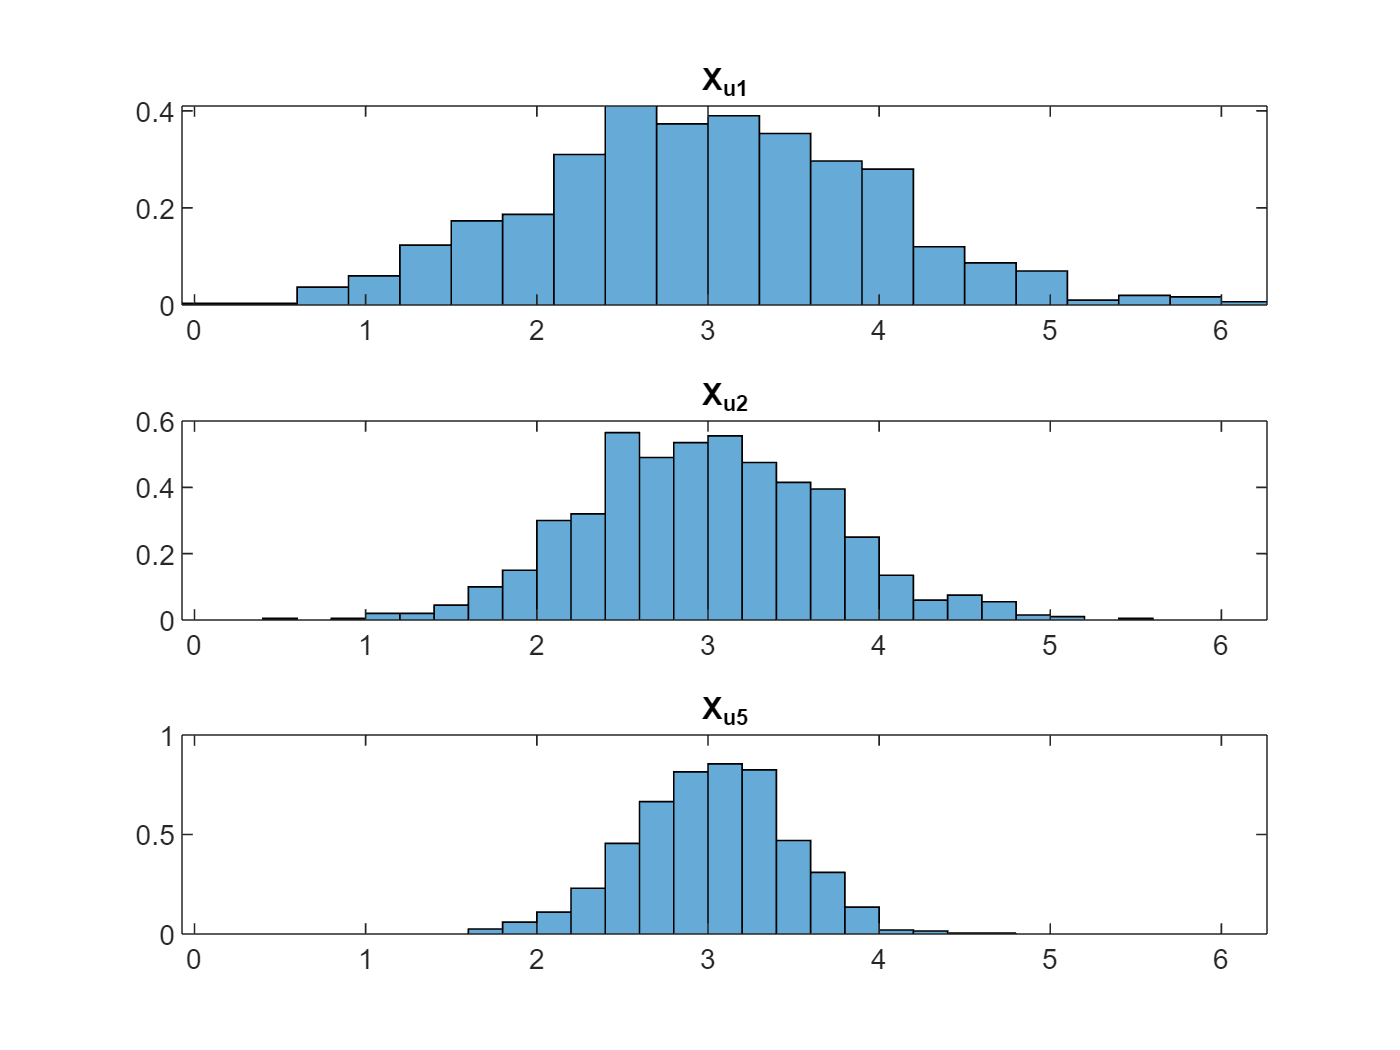

clear all
close all
clc

%------------------------------------------------
% Monte Carlo simulation
%------------------------------------------------
% your code goes here (~10 lines of code, excluding the plotting code)
mean = 3;
sigma = 1;
X_i = randn(5, 1000) * sigma + mean;

X_u1 = X_i(1, :);
X_u2 = sum(X_i(1:2, :), 1)/2;
X_u5 = sum(X_i, 1)/5;

min_u1 = min(X_u1);
max_u1 = max(X_u1);

figure(1)
subplot(3, 1, 1)
histogram(X_u1, 'Normalization', 'pdf')
xlim([min_u1 max_u1])
title("X_{u1}")

figure(1)
subplot(3, 1, 2)
histogram(X_u2, 'Normalization', 'pdf')
xlim([min_u1 max_u1])
title("X_{u2}")

figure(1)
subplot(3, 1, 3)
histogram(X_u5, 'Normalization', 'pdf')
xlim([min_u1 max_u1])
title("X_{u5}")

c) Do the plots of assignments (b) follow the analytical results that you found in answer (a)? Can you give a general statement about the mean and variance of a RV which consists of the normalized sum of $N$ RVs with same distribution and finite mean and variance? 

**ANSWER:**

**Yes it follows the analytical results, because the mean stays the same in all three cases, but the width of the histograms becomes smaller as the N becomes larger. The mean of the RV stays the same as the single RV in the sum, and the variance reduces as N increases. More precisely the variance of the final RV is N times reduced compared to the variance of the initial RV.**

## **Assignment 2 - Autocorrelation and power spectral density**

In this section, we will filter an input signal, which is a discrete random process, to generate an output signal, which is a new discrete random processes. We will study the statistical properties of the output process and its relation with the input process and the filtering operation. The figure below a system in which the input signal $x\left\lbrack n\right\rbrack$ is a white Gaussian random process with zero mean and unit variance. This input signal $x\left\lbrack n\right\rbrack$ is used as the input to a Low Pass Filter (LPF), from which the impulse response is denoted by $h\left\lbrack n\right\rbrack$ and the frequency response by $H\left(e^{j\theta } \right)$.

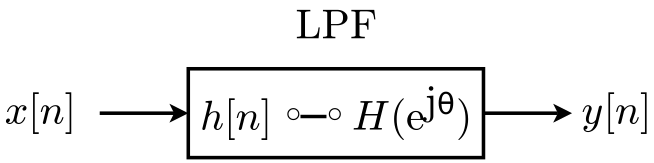

In first instance we are using the very simple LPF:


$$h\left\lbrack n\right\rbrack =\frac{1}{2\;}\left(\delta \left\lbrack n\right\rbrack +\delta \left\lbrack n-1\right\rbrack -\delta \left\lbrack n-2\right\rbrack \right)$$


Thus, in this case the output random process y[n] can be described by the following difference equation:


$$y\left\lbrack n\right\rbrack =\frac{1}{2\;}\left(x\left\lbrack n\right\rbrack +x\left\lbrack n-1\right\rbrack -x\left\lbrack n-2\right\rbrack \right)$$


which implies that the output samples are averaged values of 3 succeeding input samples.

a) Derive by hand the autocorrelation$r_y \left\lbrack l\right\rbrack =E\left\lbrace y\left\lbrack n\right\rbrack y\left\lbrack n-l\right\rbrack \right\rbrace$ of the random process $y\left\lbrack n\right\rbrack$.

**ANSWER:**


$$r_y[l] = E\{\frac{1}{2}(x[n]+x[n-1]-x[n-2])\cdot \frac{1}{2} (x[n-l] +x[n-1-l]-x[n-2-l])\}$$
 


$$r_y[l]= \frac{1}{4}(E\{x[n]\cdot x[n-l]\} + E\{x[n]\cdot x[n-1-l]\} - E\{x[n]\cdot x[n-2-l]\} + \\ \quad \quad E\{x[n-1]\cdot x[n-l]\} + E\{x[n-1]\cdot x[n-1-l]\} - E\{x[n-1]\cdot x[n-2-l]\} -\\ \quad \quad E\{x[n-2]\cdot x[n-l]\} - E\{x[n-2]\cdot x[n-1-l]\} + E\{x[n]\cdot x[n-2-l]\})$$



$$r_y[l] = \frac{1}{4}(\delta[n-n+l] + \delta[n-n+1+l] - \delta[n-n+2+l] + \delta[n-1-n+l] + \delta[n-1-n+1+l] -\delta[n-1-n+2+l]-\delta[n-2-n+l] -\delta[n-2-n+1+l]+\delta[n-n+2+l])$$



$$r_y[l] = \frac{1}{4}(\delta[l] + \delta[l+1] -\delta[l+2] +\delta[l-1]+\delta[l]-\delta[l+1]-\delta[l-2]-\delta[l-1]+\delta[l])$$



$$r_y[l] = \frac{1}{4} (3\cdot \delta[l] -\delta[l+2]-\delta[l-2])$$


b) Derive by hand the PSD $P_y \left(e^{j\theta } \right)$ of the random process $y\left\lbrack n\right\rbrack$ in two different ways, namely first as the FTD of $r_y \left\lbrack l\right\rbrack$ and second as $P_y \left(e^{j\theta } \right)=P_x \left(e^{j\theta } \right)\cdot \left|H\left(e^{j\theta } \right){\left|\right.}^2 \right.$. Please simplify  your final results as a function of 'cos' or 'sin' with the help of Euler's formula. 

**ANSWER:**

1) FTD of $r_y[l]$


$$P_y(e^{j\theta}) = F\{r_y[l]\} = \frac{1}{4} (3 \cdot F(\delta[l]) - F(\delta[l+2]) - F(\delta[l-2]))$$



$$P_y(e^{j\theta}) = \frac{3}{4} - \frac{e^{-2j\theta}}{4} - \frac{e^{2j\theta}}{4} = \frac{3}{4} - \frac{\cos(2\theta) - j\sin(2\theta)}{4} - \frac{\cos(2\theta)+j\sin(2\theta)}{4} = \frac{3}{4} - \frac{\cos(2\theta)}{2}$$


2) Using the formula $P_y(e^{j\theta}) = P_x(e^{j\theta})\cdot |H(e^{j\theta})|^2$


$$P_x(e^{j\theta}) = 1 \Rightarrow P_y(e^{j\theta}) = |H(e^{j\theta})|^2$$



$$|H(e^{j\theta})|^2 = |\frac{1}{2}(1 + e^{-j\theta} - e^{-2j\theta})|^2 = |\frac{1}{2}(1+\cos(\theta) -\cos(2\theta) - j\sin(\theta) +j\sin(2\theta))|^2$$



$$|H(e^{j\theta})|^2 = \frac{(1+\cos(\theta)-\cos(2\theta))^2 + (\sin(2\theta)-\sin(\theta))^2}{4}$$



$$|H(e^{j\theta})|^2 = \frac{1+\cos^2(\theta)+\cos^2(2\theta) + 2\cos(\theta) - 2\cos(2\theta) - 2\cos(\theta)\cos(2\theta) + \sin^2(2\theta)+\sin^2(\theta) - 2\sin(2\theta)\sin(\theta)}{4}$$



$$|H(e^{j\theta})|^2 = \frac{3}{4} +\frac{2(\cos(\theta)-\cos(2\theta)-\cos(\theta)\cos(2\theta) - \sin(2\theta)\sin(\theta))}{4}$$



$$\cos(\theta)-\cos(\theta)\cos(2\theta)-\sin(2\theta)\sin(\theta) = \cos(\theta) -\cos(\theta)(\cos^2(\theta)-\sin^2(\theta)) - 2\cos(\theta)\sin^2(\theta)=cos(\theta)-\cos(\theta)(1-2\sin^2(\theta))-2cos(\theta)\sin^2(\theta) = 0$$



$$|H(e^{j\theta})|^2 = \frac{3}{4} -\frac{\cos(2\theta)}{2} \Rightarrow P_y(e^{j\theta}) = \frac{3}{4} -\frac{\cos(2\theta)}{2}$$


c) Now, generate 1000 IID samples of $x\left\lbrack n\right\rbrack$ and use these samples to generate the samples of $y\left\lbrack n\right\rbrack$.

Generate 3 scatter plots using 'subplot(1,3,p)' (with p=1,2,3). The first scatter plot should consist of points ($y\left\lbrack n\right\rbrack ;y\left\lbrack n\right\rbrack$) ($n=1,2,\ldotp \ldotp \ldotp ,900$). Notice that this correlates samples that are separated by a ’lag’ of 0 samples. The other 2 scatter plots should consist of the points ($y\left\lbrack n\right\rbrack ;y\left\lbrack n+1\right\rbrack$), ($y\left\lbrack n\right\rbrack ;y\left\lbrack n+2\right\rbrack$), (all for $n=1,2,\ldotp \ldotp \ldotp ,900$). 

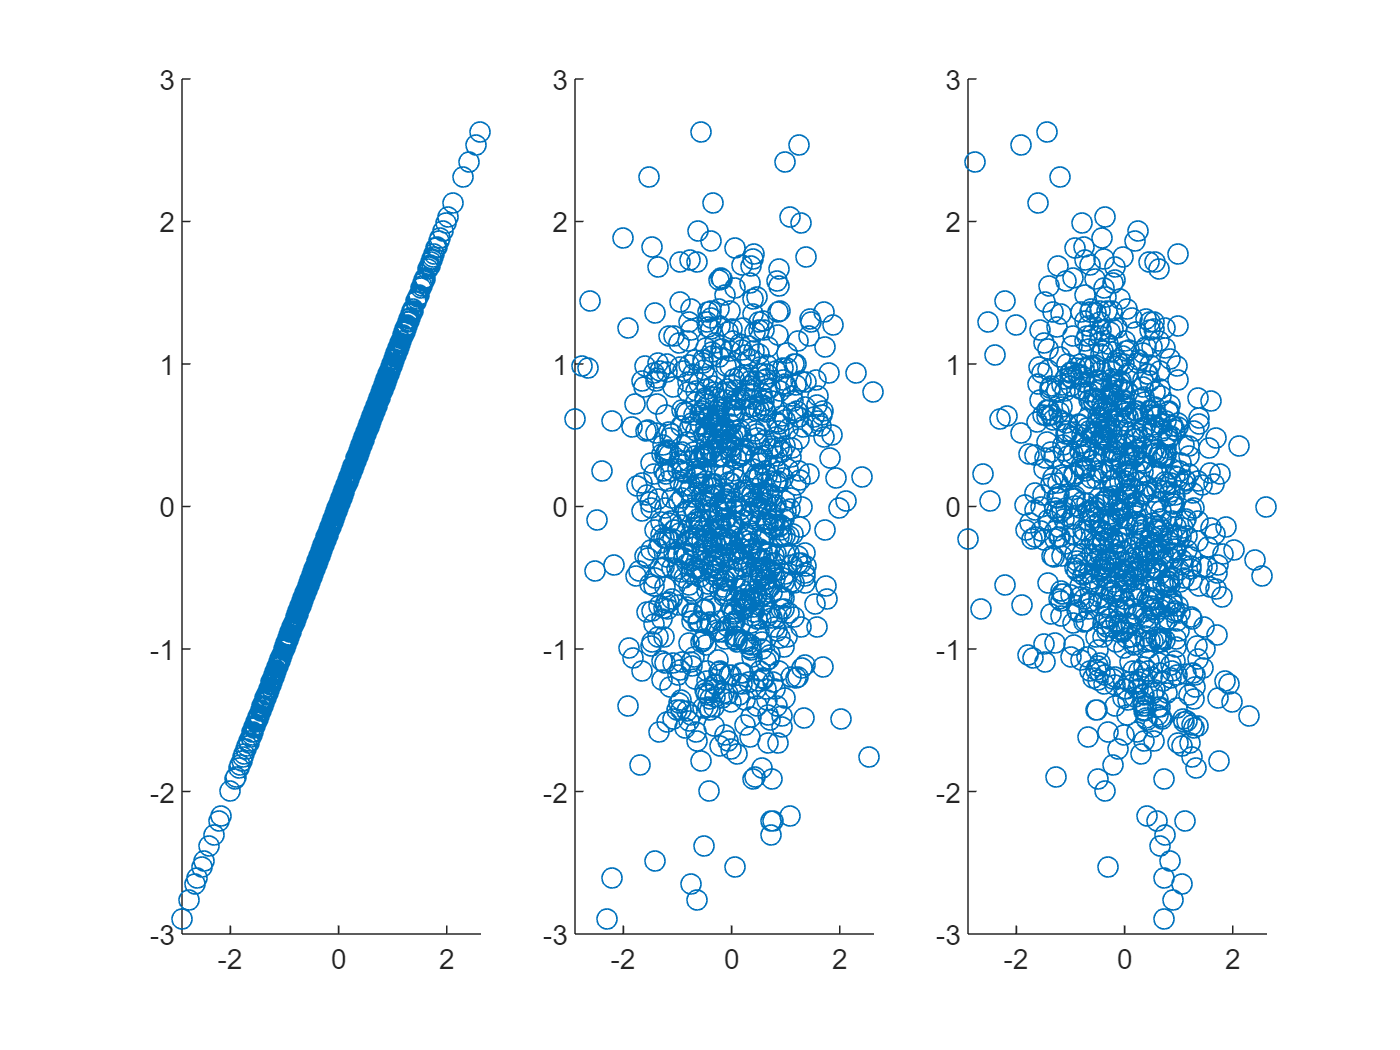

clear all
close all
clc

sigma = 1;
mean = 0;
x = randn(1,1000)*sigma + mean;
h = [1/2 1/2 -1/2];
y = conv(x,h);
%------------------------------------------------
% Realization and visual inspection of the plots
%------------------------------------------------
% your code goes here (~6 lines of code, excluding the plotting code)

figure(2)
subplot(1, 3, 1)
scatter(y(1:900), y(1:900))

figure(2)
subplot(1, 3, 2)
scatter(y(1:900), y(2:901))

figure(2)
subplot(1, 3, 3)
scatter(y(1:900), y(3:902))

d) What can you deduce about the random process$y\left\lbrack n\right\rbrack$ from these plots?

**ANSWER:**

## **Assignment 3 - Empirical correlation and PSD function**

In most real applications the following expression to estimate the autocorrelation is used: 

$\hat{r_y \left\lbrack l\right\rbrack } =\frac{1}{M}\sum_{n=0}^{M-\left|l\right|-1} y\left\lbrack n\right\rbrack y\left\lbrack n+\left|l\right|\right\rbrack$    for $-\left(L-1\right)\le l\le \left(L-1\right)$

where $M$ is the number of used samples of the sequence $y\left\lbrack n\right\rbrack$ and $L\ll M$. In the next assignment we take $L=21$. 

a) Write the code to calculate $\hat{r_y } \left\lbrack l\right\rbrack$ of the LPF defined in the previous assignment. Make one stem plot with the theoretical values $r_y \left\lbrack l\right\rbrack$ (use the result from assignment 2) and the estimated values $\hat{r_y } \left\lbrack l\right\rbrack$ versus $l$ for $-20\le l\le 20$.

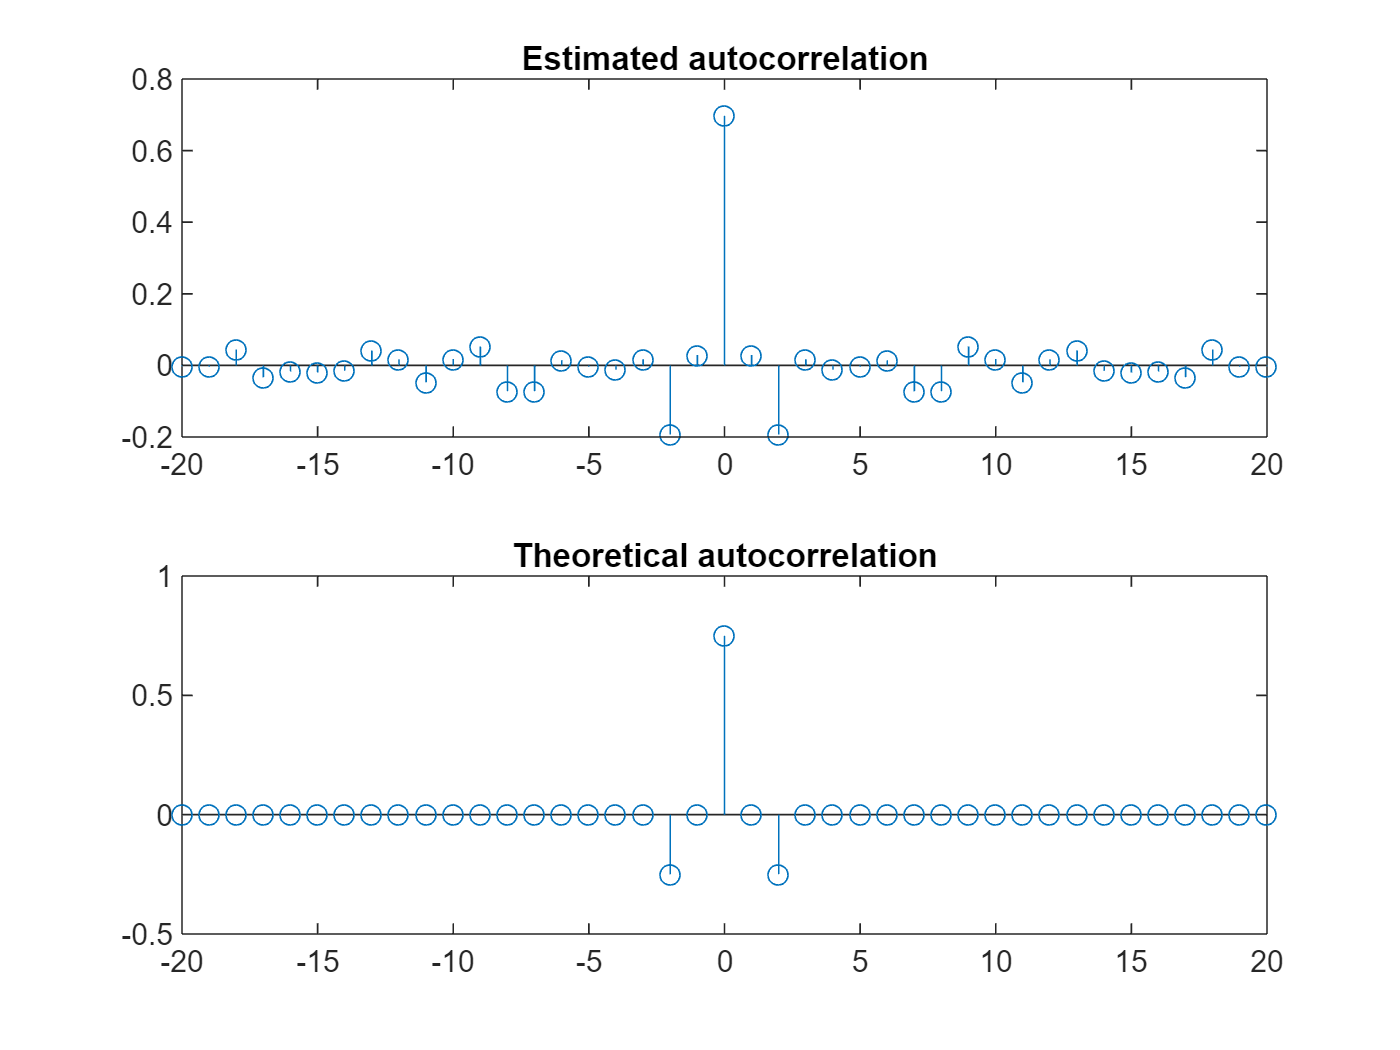

clear all
close all
clc


%------------------------------------------------
% Evaluation of the empirical autocorrelation
%------------------------------------------------
% your code goes here (~20 lines of code, excluding the plotting code)
sigma = 1;
mean = 0;
x = randn(1,1000)*sigma + mean;
h = [1/2 1/2 -1/2];
y = conv(x,h);

M = 500;
r_y = zeros(1, 41);
for l = -20:20
    r_y(l+21) = (sum(y(1:M-abs(l)).*y(abs(l)+1:M)))/M;
end

figure(3)
subplot(2,1,1)
stem(-20:20, r_y)
title('Estimated autocorrelation')
r_y_correct = zeros(1, 41);

r_y_correct(21) = 3/4;
r_y_correct(19) = -1/4;
r_y_correct(23) = -1/4;

subplot(2, 1, 2)
stem(-20:20, r_y_correct)
title('Theoretical autocorrelation')

(b) For what value of lag $l$ does $r_y \left\lbrack l\right\rbrack$ reach its maximum and for what value of lag $l$ does $\hat{r_y } \left\lbrack l\right\rbrack$ reach its maximum?

**ANSWER:**

**The maximum is reached for l=0 for both theoretical and estimated autocorrelation.**

(c) Think of a procedure to obtain an estimate of the PSD that can be derived from the calculated values $\hat{r_y } \left\lbrack l\right\rbrack$. Apply this procedure to calculate an estimate of the PSD $\hat{P_y } \left(e^{j\theta } \right)$ for $\theta$ in the range $-\pi <\theta \le \pi$. Finally make one plot with the theoretical (use the result from assignment 2) and estimated values of the PSD.

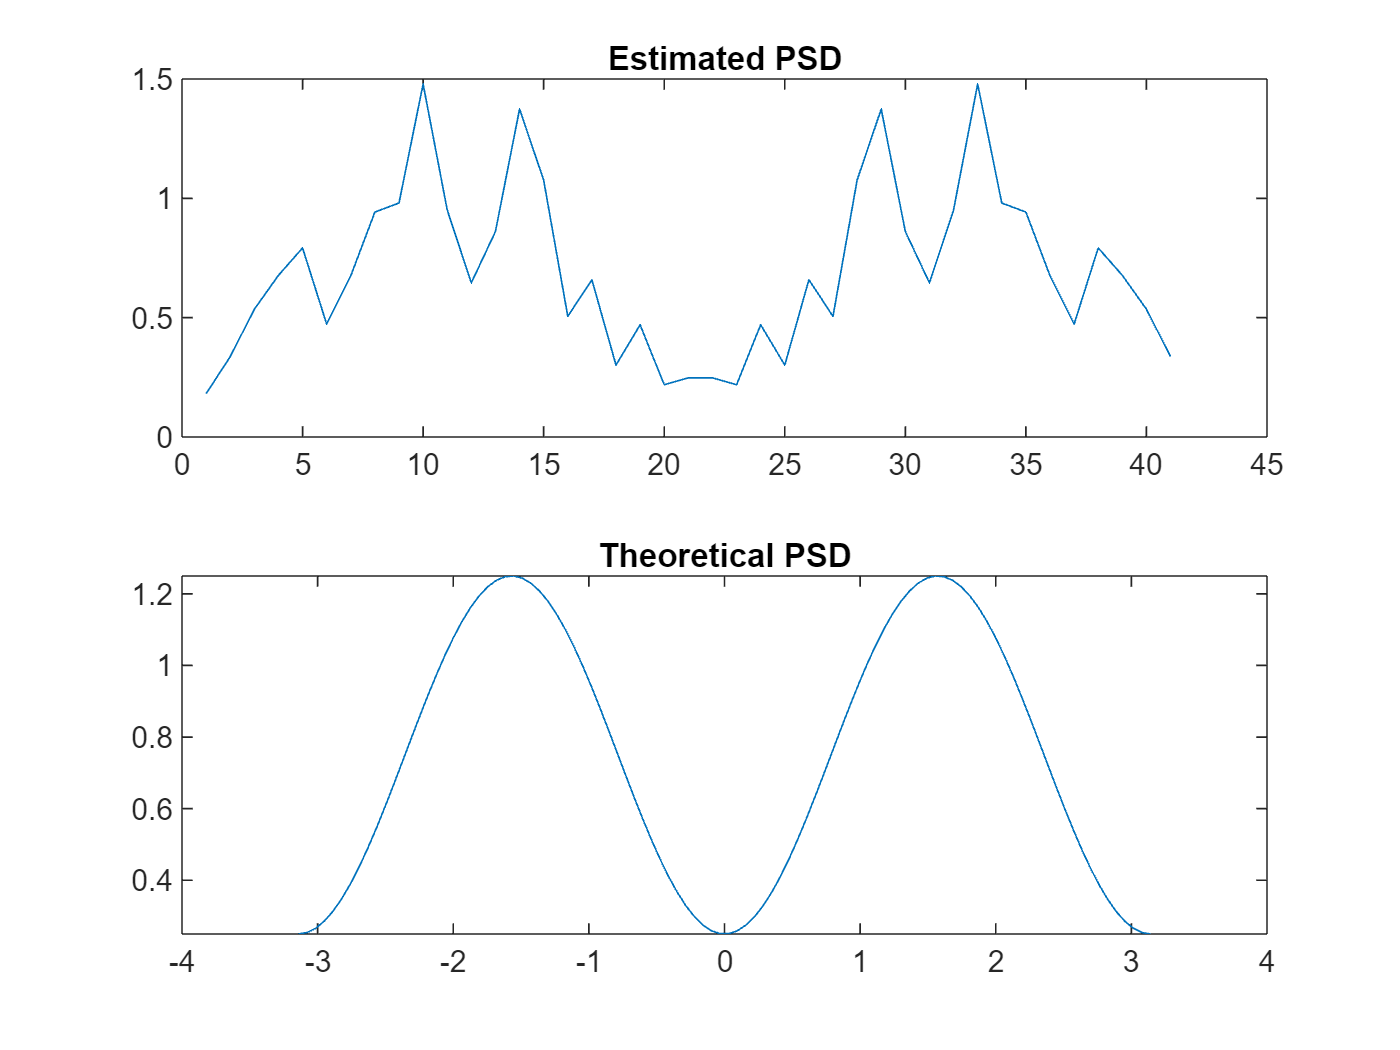

%------------------------------------------------
% Evaluation of the empirical PSD
%------------------------------------------------
% your code goes here (~3 lines of code, excluding plotting code)

theta = linspace(-pi, pi, 100);
P_y_correct = 3/4 - cos(2.*theta)/2;
P_y_estimated = fft(r_y);

figure(4)
subplot(2, 1, 1)
plot(abs(P_y_estimated))
title('Estimated PSD')
subplot(2, 1, 2)
plot(theta, P_y_correct)
title('Theoretical PSD')

(d) Give a short reasoning of possible differences between the theoretical and estimated values of the PSD.

**ANSWER:**

## **Assignment 4 - Coss-correlation of two random processes**

Cross-correlation of signals is often used in applications where we need to estimate the distance to a target (e.g., in sonar and radar). 

In a basic set-up, a zero-mean signal $x\left\lbrack n\right\rbrack$ is transmitted, which then reflects off a target after traveling for $\frac{\tau }{2}$ seconds. The reflected signal is received, amplified, and then digitized to form $y\left\lbrack n\right\rbrack \ldotp$If we summarize the attenuation and amplification of the received signal by the constant $\alpha$, then we can model the received signal as follows:


$$y\left\lbrack n\right\rbrack =\alpha x\left\lbrack n-\tau \right\rbrack +w\left\lbrack n\right\rbrack$$
 

where $w\left\lbrack n\right\rbrack$ represents additive noise from the environment and receiver electronics. 

Furthermore, we assume that $x\left\lbrack n\right\rbrack$ and $w\left\lbrack n\right\rbrack$ are uncorrelated zero-mean random variables. In order to compute the distance we need to compute the delay $\tau$. We can do this by using the cross-correlation $r_{\textrm{xy}} \left\lbrack l\right\rbrack =E\left\lbrace x\left\lbrack n\right\rbrack y\left\lbrack n+l\right\rbrack \right\rbrace$.

a) Give a short derivation in which you show the following relation: $r_{\textrm{xy}} \left\lbrack l\right\rbrack =\alpha r_x \left\lbrack l-\tau \right\rbrack$

**ANSWER:**


$$r_{xy}[l] = E\{x[n]y[n+l]\} = E\{x[n]\cdot(\alpha x[n+l-\tau] + w[n+l])\}$$



$$r_{xy}[l] = E\{\alpha x[n]x[n+l-\tau]\} + E\{x[n]w[n+l]\} = \alpha E\{x[n]x[n+l-\tau]\}$$


As $x[n]$ and $w[x]$ are uncorrelated then $E\{x[n]w[n+l]\} = 0$.


$$r_{xy}[l] = \alpha r_x[l-\tau]$$


b) From this result, describe shortly a procedure to estimate the delay $\tau$ based on measurements of the cross-correlation.

**ANSWER: **

The delay $\tau$ can be estimated as the argmax of the cross-correlation.

## Assignment 5 - Estimate delay for radar data

This assignment illustrates how the cross-correlation can be used to estimate the time-delay.

Download the MAT file radar_XX.mat (where XX represents your group number) and load it using the 'load' command. The vectors *x_tx* and *y_rx* contain two signals corresponding to the transmitted and received signals, repsectively, for a radar system. 

a) Plot the transmitted and the received signals on a single figure using *subplot*. Can you estimate the delay $\tau$ by visual inspection? 

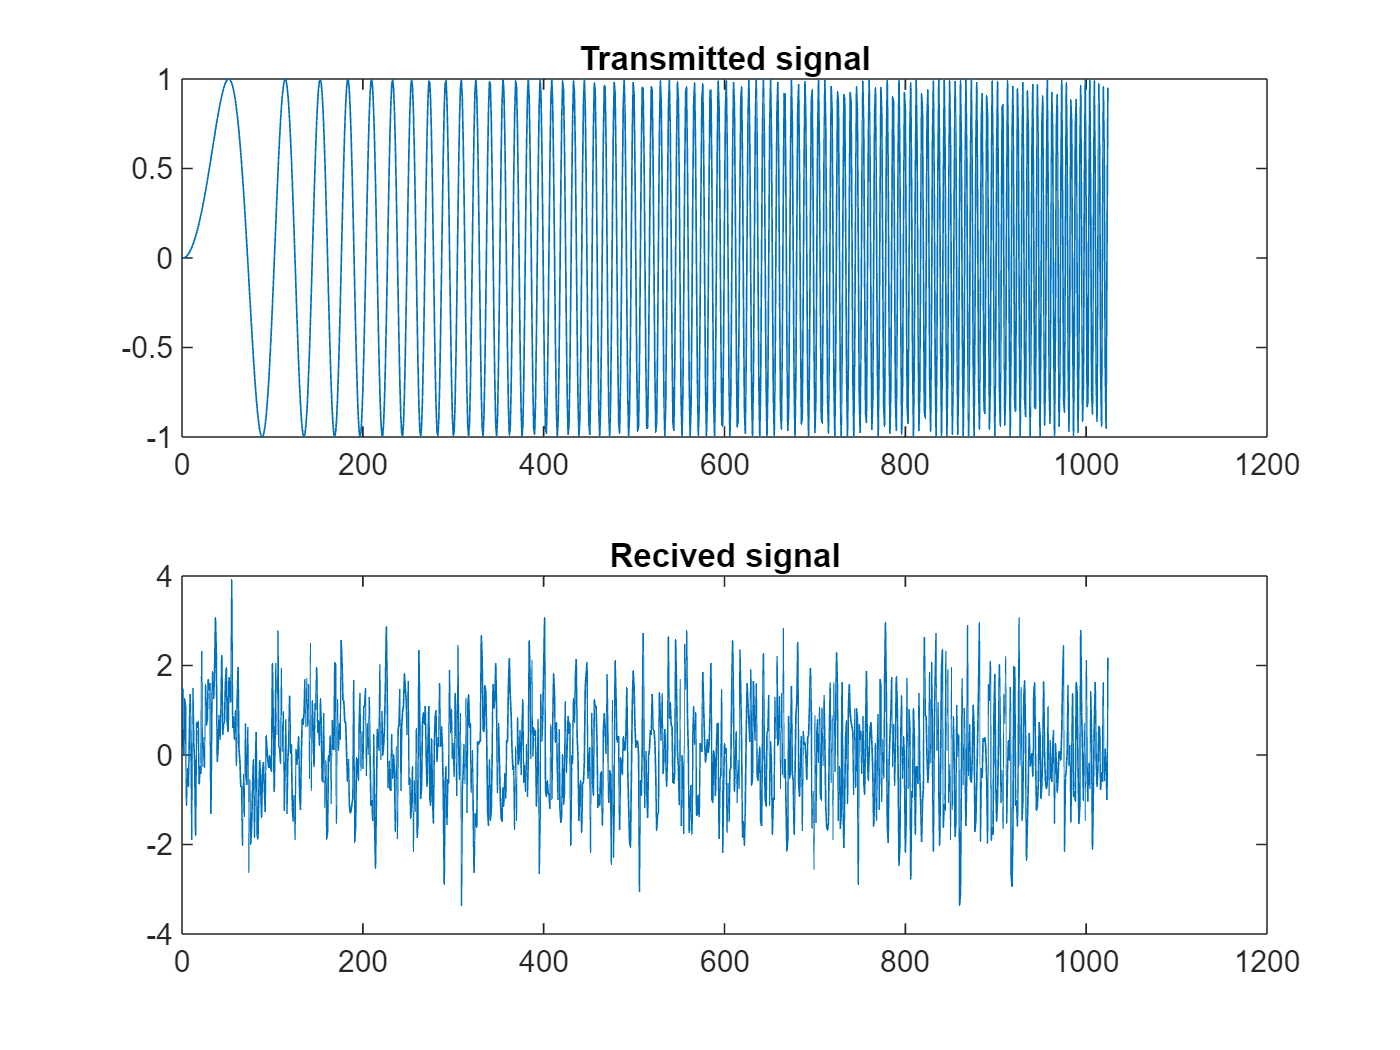

clear all
close all
clc

%------------------------------------------------
% Plot of the data
%------------------------------------------------
% your code goes here (basically only plotting code)
load("./radar_files/Radar_4.mat")

figure(5)
subplot(2, 1, 1)
plot(x_tx)
title('Transmitted signal')
subplot(2, 1, 2)
plot(y_rx)
title('Recived signal')

b) Use the function *xcorr* to calculate the sample cross-correlation between the transmitted and received signals. Plot the obtained cross-correlation in the range $-100\le l\le 100$. Can you visually estimate the delay? 

**ANSWER:**

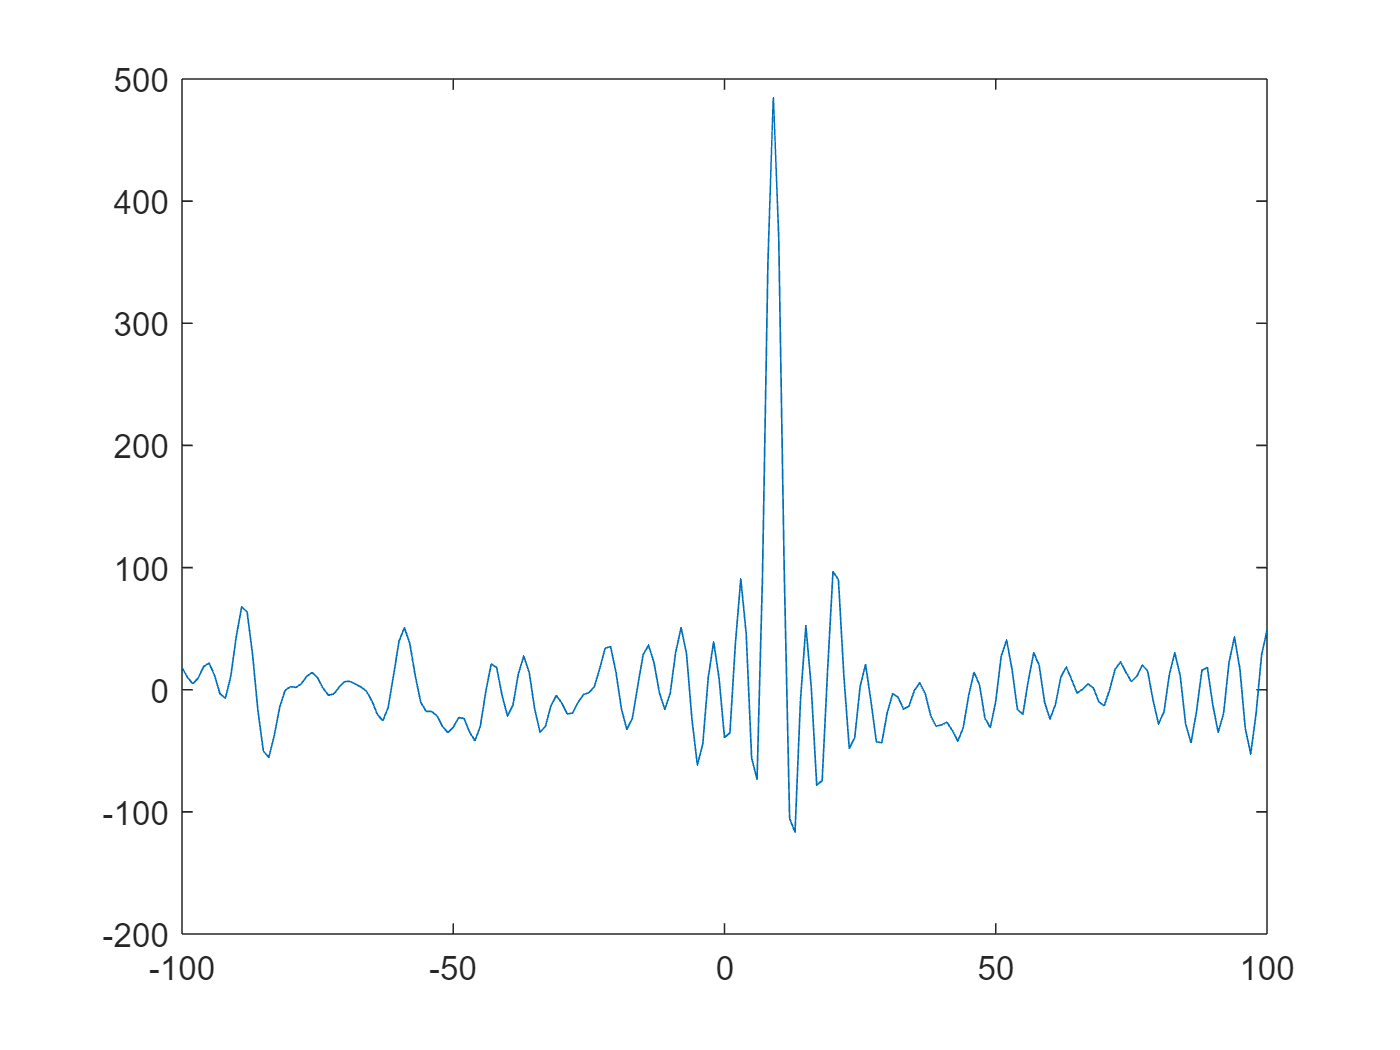


%------------------------------------------------
% Plot of the cross-correlation
%------------------------------------------------
% your code goes here (~3 lines of code, excluding plotting code)
r_xy = xcorr(x_tx, y_rx, 100);
figure(6)
plot(-100:100, r_xy)

c) Implement the MATLAB function *tau=delayestimator(x,y)* which calculates the delay between two signals using the cross-correlation function.

Save the function in the same folder of this livescript file and copy the code in the section below, but not in a code section.

%----------------------------------------------

%Delay estimator function

%----------------------------------------------

% your code goes here (~8 lines of code)

d) Test your function by generating two 1000-long sequences of zero-mean Gaussian random variables, denoted as $x\left\lbrack n\right\rbrack$ and $z\left\lbrack n\right\rbrack$. Then compute a new sequence $y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack +z\left\lbrack n\right\rbrack$. What is the estimated delay between $x\left\lbrack n\right\rbrack$ and $y\left\lbrack n\right\rbrack$? 

**ANSWER:**

%------------------------------------------------
% Test of the function
%------------------------------------------------
% your code goes here (~4 lines of code)


e) Use your function to calculate the delay between the transmitted and received signals.

%------------------------------------------------
% Evaluation of tau
%------------------------------------------------
% your code goes here (1 line of code)


## Part 2 - Estimation theory

## Introduction

In this lab, we will apply concepts of estimation theory and hypothesis testing, using as a case example the diagnostic imaging for prostate cancer.

One of the most common imaging modalities used in the diagnostic workup of prostate cancer is contrast-enhanced ultrasound (CEUS). As illustrated in Fig. 1, during a CEUS examination, the patient is injected with a contrast agent and the organ of interest is scanned by using contrast-specific ultrasound scanning sequences, obtaining an ultrasound video (2D image + time). The contrast agents used for ultrasound imaging are made of microbubbles of about 5 $\mu$m in diameter. Because of their size, they cannot cross the vascular wall, and thus they are defined as intravascular contrast agents. As shown in Fig. 1, if we extract the ultrasound intensity at one single pixel over time, we obtain a time-intensity curve (TIC). When the TIC is properly linearized (inverting log-compression and time-gain compensation applied by the ultrasound scanner), then the TIC can be directly related to the changes in contrast agent concentration over time.

 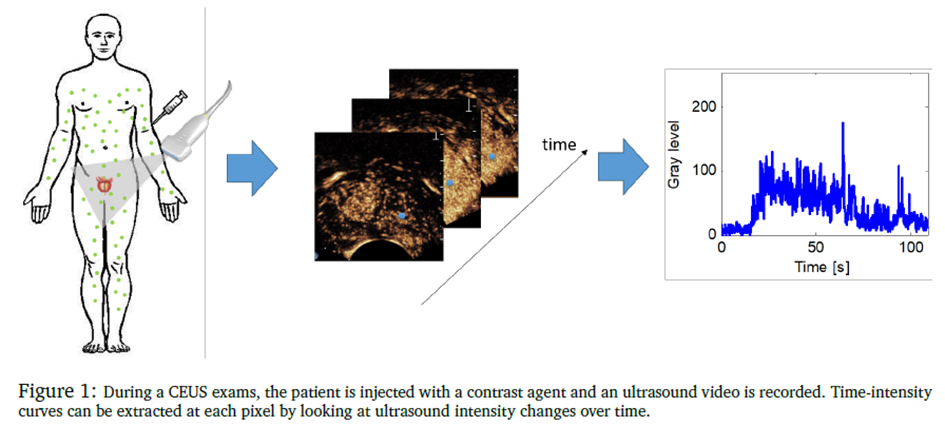

Over the years, several models have been developed to describe the transport of contrast particles in the vasculature. In this lab, we will use the modified local density randon walk model (mLDRW). The random walk family of models for contrast concentration curves are obtained by modeling the physical process of contrast agent transport as a dispersion process superimposed to a linear drift. At any time, the contrast concentration in space is given by a Gaussian distribution. In time, the mean of this distribution moves with the same velocity as the carrier fluid (e.g., blood) and the variance increases linearly with time. This results in a skewed distribution in time. Assuming a linear relationship between the contrast agent concentration and the intensity in the ultrasound video, the mLDRW model describes the video intensity at each pixel as

$I\left(t\right)=\textrm{AUC}\sqrt{\frac{\kappa }{2\pi t}}e^{-\frac{{\kappa \left(t-\mu \;\right)}^2 }{\;2t}} +I_0$     (1)

where $\mu \;$represents the mean transit time,  $\kappa \;$is a skewness parameter related to the dispersion of the contrast agent particles through the circulation, $I_0$ is the baseline, and the AUC is the area under the TIC. 

By normalizing by the AUC and subtracting the baseline, the model in (1) can be interpreted as the probability distribution of transit time of contrast particles as

$p\left(t\left|\Theta \;\right.\right)=\sqrt{\frac{\kappa }{2\pi t}}e^{-\frac{{\kappa \left(t-\mu \;\right)}^2 }{\;2t}}$                (2)

where $\Theta =\left\lbrack \mu ,\kappa \;\right\rbrack$. Normalization by the AUC in fact ensures that (2) integrates to 1.

Research has shown that the parameters of the mLDRW model are related to vascular features of tissue, which may be altered in cancer. By estimating the parameters of the mLDRW model at each pixel in the ultrasound video, a parametric map can be obtained and used to diagnose cancer. An example is shown in Fig. 2. Parameter estimation is performed by fitting TICs extracted at each pixel of the US video by the mLDRW model, thus obtaining estimated values of  and  at each pixel. In Fig. 2, the estimated  parameter is shown in the form a colormap, which assigns a different color at each pixel depending on the parameter value. The ground truth is represented by the microscopic analysis of the prostate performed after surgical resection (radical prostatectomy). The pathologist performing the analysis marks in red the regions where cancer was present. Comparing the parametric map of $\kappa$ with the ground truth, we see a good match. It suggests that the parameter $\kappa$ is higher where cancer is present.

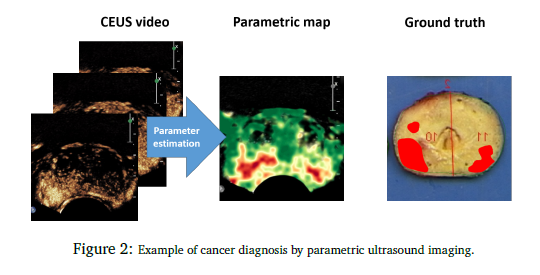

## 1. Parameter estimation 

In the following assignments, you will implement least-square estimation (LSE) and maximum likelihood estimation (MLE) to estimate the parameters in (1). The parameter AUC is given, while $\mu$ and $\kappa$ are unknown. The files required to carry out the assignments are provided in the ***Lab1Part2Data*** folder.. For assignments 1 and 2, you will work with the file ***curve_fitting.mat***. This contains a vector TIC, which represents the intensity of the ultrasound video over time, a vector time, representing the time in seconds, and variable AUC, representing the given value for the parameter AUC.

The goal of the first assignment is to obtain least-square estimates for the parameters $\mu$ and $\kappa$, assuming that the model generating the observed data is given by (1). Since (1) is non-linear, you will implement non-linear LSE. For this, a template function named ***nl_lse_mldrw*** is provided in the parent folder ‘Lab2data’.

## Assignment 6 - Least-square estimaiton 

a) Derive the first derivatives of the model in (1) with respect to $\mu$ and $\kappa$, considering AUC as constant.


$$\frac{dI}{dk}=AUCe^\frac{-k(t-\mu)^2}{2t}\left(\frac{1}{4\pi t\sqrt{\frac{k}{2\pi t}}}-\frac{(t-\mu)^2}{2t}\sqrt{\frac{k}{2\pi t}}\right)$$



$$\frac{dI}{dt}=A U C e^{-\frac{-k(t-\mu)^2}{2 t}}\left(-\frac{k}{4 \pi t^2 \sqrt{\frac{4}{2 \pi t}}}-\frac{k(t-\mu)(t+\mu)}{2 t^2} \sqrt{\frac{k}{2 \pi t}}\right)$$


b) Implement a MATLAB function for non-liner LSE by the Gauss-Newton method. To do so, use the provided template function ***nl_lse_mldrw(curve, time, init_guess, maxiter, tolerance)***. Use as initial guesses for the parameter estimates $\mu {\;}_{\textrm{init}} =10$ and $\kappa_{\textrm{init}} =0\ldotp 5$. Normalize the TIC by the AUC value and apply the implemented function to estimate the model parameters from TIC_norm=TIC/AUC (e.g., the observed TIC after the normalization).

(c) Repeat curve fitting by using the built-in MATLAB function ***lsqcurvefit*** and compare the results.

**Hint:** Read the MATLAB documentation for lsqcurvefit. Use the appropriate option to set boundaries for the parameters estimates in order to impose a non-negative value for both $\mu$ and $\kappa$.

% Assignment 6 code 

% b) Complete the missing part in nl_lse_mldrw then implement LSE 

% c) Use lsqcurvefit 

Each dataset is the result of a realization of the experiment, which is, in this example, the injection of contrast particles into the body for imaging an organ. The random variable is the arrival time of the particles at the detection point (e.g., one imaging pixel inside the organ). Points constituting the observation are drawn from a distribution. The maximum likelihood estimation (MLE) is based on the dependence between the probability of the observation of an outcome and the parameters controlling the distribution. The MLE is the answer to the question: “What should be the controlling parameters such that the observation we made is the most likely one?". To answer this question, we need the log-likelihood function $\ln \mathcal{L}$, which is the natural logarithm of the likelihood function. The Likelihood function itself is derived from the probability density function $p\left(t\left(k\right),\theta \right)$ for the samples of the observation we have, which is a function of both the data and the parameters controlling the probability density function. MLE consists of finding the controlling parameters $\theta \;$ that maximize the log-likelihood function, that is $\mathcal{L}(\theta): \theta_{mle}=arg_{\theta} \max\ln\mathcal{L}(\theta)$.

## Assignment 7 - Maximum likelihood estimaiton 

(a) Derive the log-likelihood for the model in (2), at the observed times $t\left(k\right)$, with $k=0,\ldotp \ldotp \ldotp ,K-1$.

**Hint:** The probability density function in (2) is continuous, but the data provided consists of measurements of number of particles at discrete time intervals. Each time sample can be seen as a single observation at $t\left(k\right)=k\Delta t$, with $k=0,\ldotp \ldotp \ldotp ,K-1$.


$$ln(p(t|\Theta ))=ln\left(\sqrt\frac{1}{2\pi\Delta t}\right)-\frac{k^2\Delta t-2\mu\Delta t + \mu^2}{2\Delta t}$$


(b) Derive by hand the ML estimators for $\mu$ and $\kappa$, i.e., ${\hat{\kappa \;} }_{\textrm{MLE}}$ and ${\hat{\mu \;} }_{\textrm{MLE}}$ Apply your derived estimators to estimate $\mu$ and $\kappa$. To do so, use the normalized data (TIC_norm=TIC/AUC) as in assignment 6.

(c) Repeat parameter estimation using the MATLAB command **mle**. Is the result the same as in (b)?

**ANSWER:**

**Hint**: Read the MATLAB documentation for mle. Look at the option ‘logpdf’ for using a custom log probability density function. Use the appropriate option to set boundaries for the parameters estimates in order to impose a non-negative value for both $\mu$ and $\kappa$.

% Assignment 7 code 

% b) Implement the log-likappaelihood derived in Question a


% c) Using mle from MATLAB


In the following assignment, we will test the performance of the two estimators implemented in assignments 1 and 2. We will use the file **perfomance.mat**, which includes a matrix TIC_reps containing 1000 observations of the same TIC, and the variables mu_true and kappa_true, representing the true parameter values.

## Assignment 8 - Estimation performance

(a) Repeat the estimation in assignments 1 and 2 for all 1000 observations of the TIC. For each repetition, calculate the $R^2$ of the fit.

(b) Make a 2x2 subplot, showing the histogram of the estimated parameters, together with their true values, for the two estimators. What can you say about bias and variance of the two estimators?

**ANSWER:**

(c) Calculate the mean and variance of the obtained estimates. Which of the two estimators performs better in terms of bias and variance? Which estimator provides, in average, the highest $R^2$?

**ANSWER:**

% Assignment 8 code

% a) repeat the estimation in assingment 1 and 2

% b) make a 2x2 subplot

% c) calculate the mean and variance 


## 2. Cancer imaging

In the following assignment, we will use the implemented estimators to visualize vascular abnormalities related to cancer in the prostate. For this assignment, we will use the file **prostate_CEUS_video.mat**, which is the parent folder ‘Lab2data’. The file contains a LxWxN matrix USvideo, where LxW represents the length and width of the ultrasound image, while N represent the number of time frames. The histology image is also provided as ‘Groundtruth.PNG’.

## Assignment 9 - Parametric maps

(a) In the matrix USvideo, each (:, :, n) represents a US image at frame n, while each (i, j, :) represents a TIC. Set n=100, and display the US image at the 100th frame. Then, choose a pixel and plot a time-intensity curve.

**Hint:** Use command squeeze to turn a 1x1xN matrix into a 1xN vector.

(b) Based on assignment 3, pick the best estimator and repeat the parameter estimation procedure for each pixel in the matrix. Save the parameters $\mu \;$ and $\kappa \;$estimated at each pixel in two matrices of dimension LxW. At each pixel, calculate the $R^2$ of the fit and set to NaN the pixels for which the $R^2 <0\ldotp 75$. For these pixels, the fit is in fact unreliable.

(c) Use the command** imagesc** to display the obtained parametric maps for $\mu \;$and $\kappa$. Compare the parametric maps with the provided histology picture, where the cancer is marked in red by a pathologist. For a better visualization of the parametric map, set the limit of the colormap to a suitable range, such as the range between the 5% and 95% percentiles. Which parameter seems most promising for cancer detection?

**ANSWER:**

**Hint:** Read the the MATLAB documentation for commands* quantile* and *imagesc*. To calculate the 5% - 95% percentile range, use command *y = quantile(x,[0.05 0.95])*, where x is a vector with all the values of the parameter to be visualized. The obtained 5% - 95% percentiles can then be passed as limits for the colormap range to the function imagesc.

Note: An easy way to turn a matrix X into a vector is by typing X(:).

% Assignment 9 code 

% a) displace the 100th US frame and plot a time-intensity curve

% b) use the best estimator in assignment 3 to calculate unknown parameters

% c) visulize parametric maps 


